## Задание 2. Синтез H2-регулятора по выходу.

Начальные условия на задание:

A = [0 1;
     0 0]

A =      0     1
     0     0


B = [0; 1]

B =      0
     1


C = [1 0;]

C =      1     0


D = [0]

D = 0


Dw = [0 1]

Dw =      0     1


Bw = [0 0 ; 
      1 0]

Bw =      0     0
     1     0


eig(A)

ans =      0
     0


**Настройка моделирования**

simTimeStart = 0;
simTimeEnd = 10;
step = 0.0001; 
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer_controller_noise'; 
load_system(modelName);

## **1- Первый набор Cz, Dz**

Cz = [1, 2;  
      0, 0]; 
Dz = [0;     
      1];  
% Проверка независимости
Cz'*Dz % == 0

ans =      0
     0


Bw*Dw' % == 0

ans =      0
     0


% Проверка невырожденности
Dw*Dw' % == scalar number

ans = 1

Dz'*Dz % == scalar number

ans = 1


% y = ampl * sin(w*t + phi)
ampl = [1 1];
phi = [pi/2 pi/2];
f = 5.2;
w = [2*pi * f 2*pi * f];

### **Рандомная частота у внешнего возмущения**

Q = Cz' * Cz

Q =      1     2
     2     4


R = Dz' * Dz

R = 1


% GET OBSERVE
P = are(A', 1*C'*R^-1 *C, Q)

P =     2.2361    2.0000
    2.0000    2.4721


L = -P*C'*R^-1

L =    -2.2361
   -2.0000


EIG_L =  eig(A + L*C)

EIG_L =   -1.1180 + 0.8660i
  -1.1180 - 0.8660i


mat2tex(L,2);

\begin{bmatrix}
    -2.24 \\
    -2 \\
\end{bmatrix}


% GET CONTROL
P = are(A, 1*B*R^-1 *B', Q)

P =     0.4495    1.0000
    1.0000    2.4495


K = -inv(R) * B' * P

K =    -1.0000   -2.4495


EIG_K =  eig(A + B * K) 

EIG_K =    -0.5176
   -1.9319


mat2tex(K,2);

\begin{bmatrix}
    -1 & -2.45 \\
\end{bmatrix}


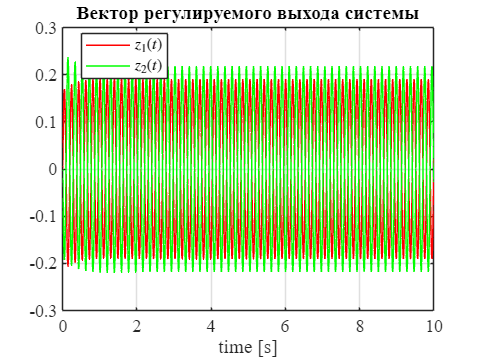

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
z = out.z_plant.Data;


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z5");

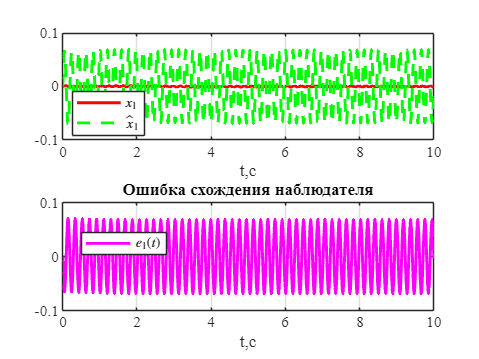

%%%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
save_file("obsv1");

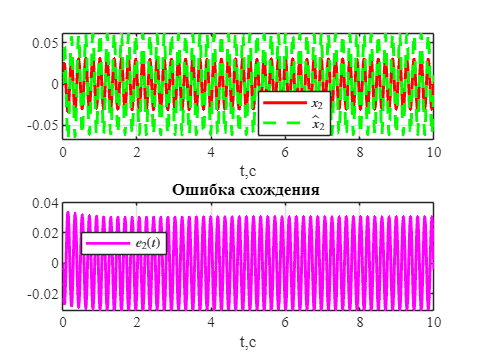

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
save_file("obsv2");

%%%%%%%%%%%%%%

### **Наихудший в каком-то смысле**

% y = ampl * sin(w*t + phi)
ampl = [1 1];
phi = [pi/2 pi/2];
f = 0.6;
w = [2*pi * f 2*pi * f];

Q = Cz' * Cz

Q =      1     2
     2     4


R = Dz' * Dz

R = 1


% GET OBSERVE
P = are(A', 1*C'*R^-1 *C, Q)

P =     2.2361    2.0000
    2.0000    2.4721


L = -P*C'*R^-1

L =    -2.2361
   -2.0000


EIG_L =  eig(A + L*C)

EIG_L =   -1.1180 + 0.8660i
  -1.1180 - 0.8660i


mat2tex(L,2);

\begin{bmatrix}
    -2.24 \\
    -2 \\
\end{bmatrix}


% GET CONTROL
P = are(A, 1*B*R^-1 *B', Q)

P =     0.4495    1.0000
    1.0000    2.4495


K = -inv(R) * B' * P

K =    -1.0000   -2.4495


EIG_K =  eig(A + B * K) 

EIG_K =    -0.5176
   -1.9319


mat2tex(L,2);

\begin{bmatrix}
    -2.24 \\
    -2 \\
\end{bmatrix}


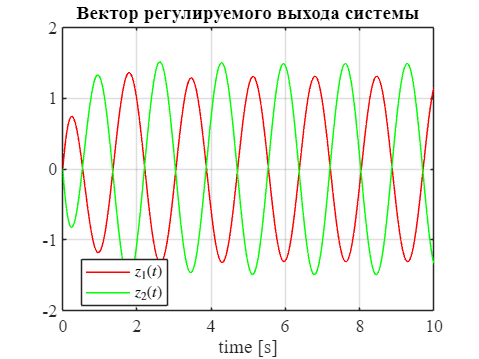

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z6");

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(2) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
          2 s^3 + 5.899 s^2 + 4.449 s + 1
   1:  -------------------------------------
       s^4 + 4.899 s^3 + 8 s^2 + 4.899 s + 1
 
         -2.449 s^3 - 7 s^2 - 4.899 s - 1
   2:  -------------------------------------
       s^4 + 4.899 s^3 + 8 s^2 + 4.899 s + 1
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Proper

disp(tf2latex(sys));

\begin{bmatrix}\frac{2s^{3} + 5.9s^{2} + 4.45s + 1}{1s^{4} + 4.9s^{3} + 8s^{2} + 4.9s + 1} & 0 \\\\ \frac{-2.45s^{3} - 7s^{2} - 4.9s - 1}{1s^{4} + 4.9s^{3} + 8s^{2} + 4.9s + 1} & 0\end{bmatrix}


tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

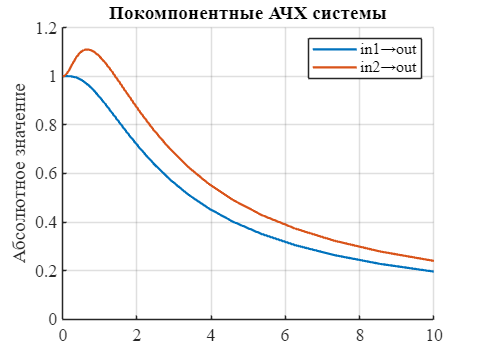

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components3");

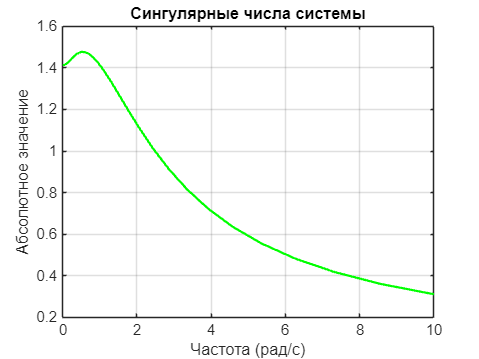

[sv, wout] = sigma(sys(:,1), {0.001,10});  % sv - массив сингулярных чисел (абсолютные значения)
sv = squeeze(sv);        

% Строим график
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values3");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 1.5651

H_inf_norm = norm(sys, inf)

H_inf_norm = 1.4776

## **2 - Второй набор Cz, Dz**

Cz = [3, 1;  
      0, 0]; 
Dz = [0;     
      2];  
% Проверка независимости
Cz'*Dz % == 0

ans =      0
     0


Bw*Dw' % == 0

ans =      0
     0


% Проверка невырожденности
Dw*Dw' % == scalar number

ans = 1

Dz'*Dz % == scalar number

ans = 4

### **Рандомная частота у внешнего возмущения**

% y = ampl * sin(w*t + phi)
ampl = [1 1];
phi = [pi/2 pi/2];
f = 3.5;
w = [2*pi * f 2*pi * f];

Q = Cz' * Cz

Q =      9     3
     3     1


R = Dz' * Dz

R = 4


% GET OBSERVE
P = are(A', 1*C'*R^-1 *C, Q)

P =     7.2111    2.0000
    2.0000    0.6056


L = -P*C'*R^-1

L =    -1.8028
   -0.5000


EIG_L =  eig(A + L*C)

EIG_L =    -1.4604
   -0.3424


mat2tex(L,2);

\begin{bmatrix}
    -1.8 \\
    -0.5 \\
\end{bmatrix}


% GET CONTROL
P = are(A, 1*B*R^-1 *B', Q)

P =     7.8167    6.0000
    6.0000    7.2111


K = -inv(R) * B' * P

K =    -1.5000   -1.8028


EIG_K =  eig(A + B * K) 

EIG_K =   -0.9014 + 0.8292i
  -0.9014 - 0.8292i


mat2tex(K,2);

\begin{bmatrix}
    -1.5 & -1.8 \\
\end{bmatrix}


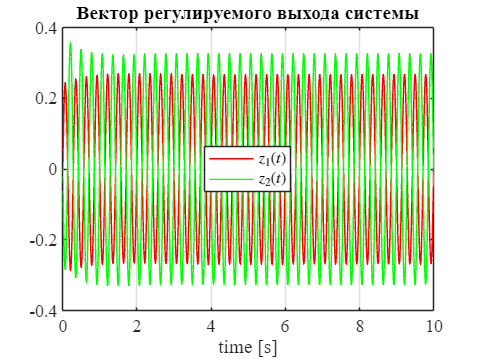

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
z = out.z_plant.Data;


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z7");

### **Наихудший в каком-то смысле**

% y = ampl * sin(w*t + phi)
ampl = [1 1];
phi = [pi/2 pi/2];
f = 0.85;
w = [2*pi * f 2*pi * f];

Q = Cz' * Cz

Q =      9     3
     3     1


R = Dz' * Dz

R = 4


% GET OBSERVE
P = are(A', 1*C'*R^-1 *C, Q)

P =     7.2111    2.0000
    2.0000    0.6056


L = -P*C'*R^-1

L =    -1.8028
   -0.5000


EIG_L =  eig(A + L*C)

EIG_L =    -1.4604
   -0.3424


mat2tex(L,2);

\begin{bmatrix}
    -1.8 \\
    -0.5 \\
\end{bmatrix}


% GET CONTROL
P = are(A, 1*B*R^-1 *B', Q)

P =     7.8167    6.0000
    6.0000    7.2111


K = -inv(R) * B' * P

K =    -1.5000   -1.8028


EIG_K =  eig(A + B * K) 

EIG_K =   -0.9014 + 0.8292i
  -0.9014 - 0.8292i


mat2tex(L,2);

\begin{bmatrix}
    -1.8 \\
    -0.5 \\
\end{bmatrix}


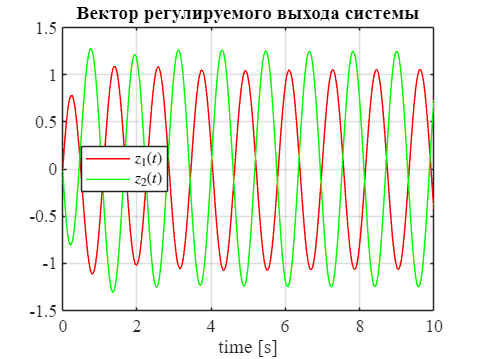

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
z = out.z_plant.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, z(:,1), 'r', 'LineWidth', 1.0); hold on
plot(time, z(:,2), 'g', 'LineWidth', 1.0); grid on;
xlabel('time [s]');                                   
legend('$z_1(t)$','$z_2(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
title('Вектор регулируемого выхода системы');
save_file("z8");

s = tf('s');
sys = (Cz + Dz*K)*(s*eye(2) - A - B*K)^-1 * Bw

sys =
 
  From input 1 to output...
             s^3 + 4.803 s^2 + 6.908 s + 4.5
   1:  -------------------------------------------
       s^4 + 3.606 s^3 + 6.25 s^2 + 5.408 s + 2.25
 
          -3.606 s^3 - 9.5 s^2 - 10.82 s - 4.5
   2:  -------------------------------------------
       s^4 + 3.606 s^3 + 6.25 s^2 + 5.408 s + 2.25
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.


disp(tf2latex(sys));

\begin{bmatrix}\frac{1s^{3} + 4.8s^{2} + 6.91s + 4.5}{1s^{4} + 3.61s^{3} + 6.25s^{2} + 5.41s + 2.25} & 0 \\\\ \frac{-3.61s^{3} - 9.5s^{2} - 10.82s - 4.5}{1s^{4} + 3.61s^{3} + 6.25s^{2} + 5.41s + 2.25} & 0\end{bmatrix}


tfs = {sys(1,1), sys(2,1)};
titles = {'in1→out',  'in2→out'};

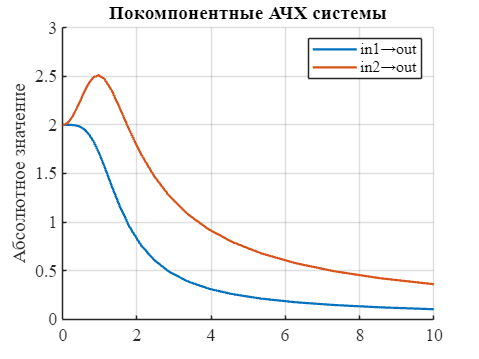

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
colors = lines(2);
hold on;
for i = 1:2
    [mag, ~, wout] = bode(tfs{i}, {0.001,10});
    plot(wout, squeeze(mag), 'Color', colors(i,:), 'LineWidth', 1.5);
end
legend(titles);
grid on;
ylabel('Абсолютное значение');
title("Покомпонентные АЧХ системы")
save_file("freq_ampl_components4");

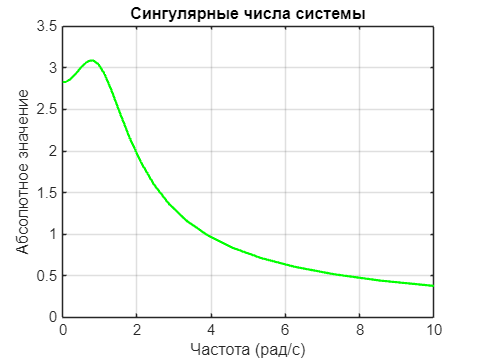

[sv, wout] = sigma(sys(:,1), {0.001,10});  % sv - массив сингулярных чисел (абсолютные значения)
sv = squeeze(sv);        

% Строим график
figure;
plot(wout, sv, 'g', 'LineWidth', 1.5);  
title('Сингулярные числа системы');
xlabel('Частота (рад/с)');
ylabel('Абсолютное значение');
grid on;
save_file("singular_values4");

% Вычисление H_2 и H_inf норм
H2_norm = norm(sys, 2) % H2_norm = sqrt(trace(Bw'*P*Bw))

H2_norm = 2.6853

H_inf_norm = norm(sys, inf)

H_inf_norm = 3.0928

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab11\latex11\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end